# Control and Instrumentation Lab Assignment 2

**SWARNENDU PAUL 19EE3FP18**

**Question 8.**

In the following 4 parts, we will plot the phase portrait and trajectory for the linear time-invariant dynamical system,

$\frac{dx(t)}{dt} = Ax(t)$ where $x(t)\in \mathbb{R}^2$ 

**8.a.**

**a. ** Here $A=[-1,1;-1,-1]$ and $x(0) = [-0.5;-0.3]$ and interval [0,10]

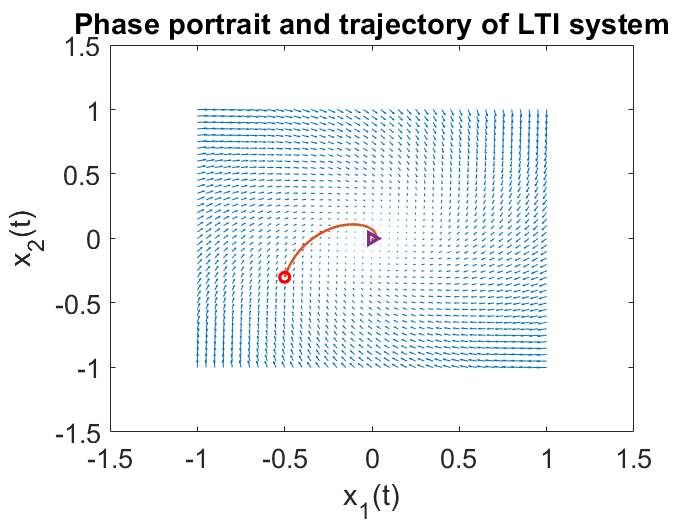

figure
[X1, X2]=meshgrid(-1:0.05:1);
A1=[-1 1;-1 -1];
vx1 = A1(1,1).*X1 + A1(1,2).*X2;
vx2 = A1(2,1).*X1 + A1(2,2).*X2;
%phase portrait
quiver(X1,X2,vx1,vx2);
[t, x] = ode45(@(t,x)A1*x,0:0.01:10,[-0.5;-0.3]);
hold on
%trajectory
plot(x(:,1),x(:,2),'LineWidth',1.5);
title("Phase portrait and trajectory of LTI system");
xlabel("x_1(t)");
ylabel("x_2(t)");
set(gca,'Fontsize',16);
%start_point
plot(x(1,1),x(1,2),"LineWidth",2,"Marker","o","Color","r");
%end_point
plot(x(1001,1),x(1001,2),"LineWidth",2,"Marker",">");
hold off

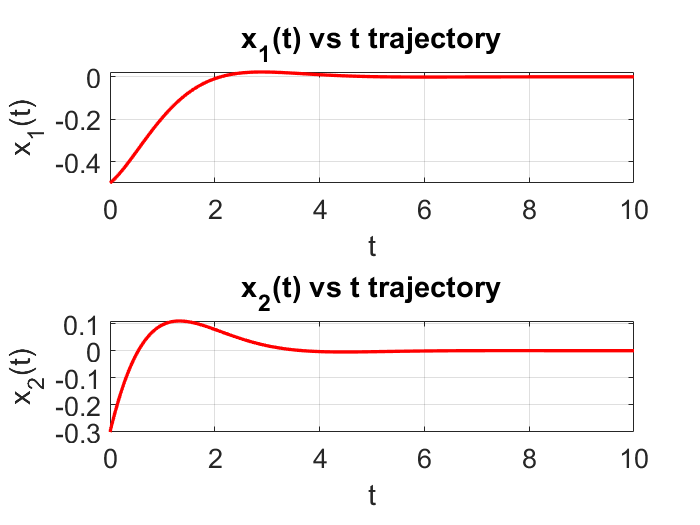

figure
%x1(t) vs t plot
subplot(2,1,1)
plot(t,x(:,1),"LineWidth",2,"Color","r");
grid on
title("x_1(t) vs t trajectory");
ylabel("x_1(t)");
xlabel("t");
set(gca,'Fontsize',16);
%x2(t) vs t plot
subplot(2,1,2)
plot(t,x(:,2),"LineWidth",2,"Color","r");
grid on
title("x_2(t) vs t trajectory");
ylabel("x_2(t)");
xlabel("t");
set(gca,'Fontsize',16);

**b. **Here $A = [0,1;-1,0]$ and $x(0) = [-0.3;-0.3]$ and time interval [0,20]

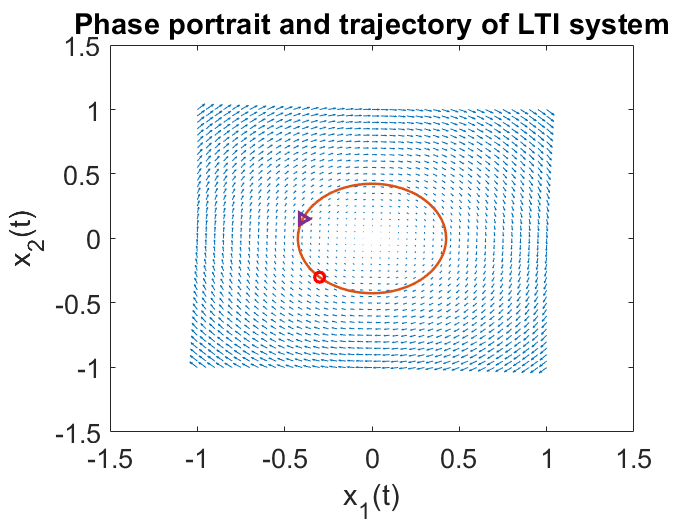

figure
A2=[0 1;-1 0];
vx1 = A2(1,1).*X1 + A2(1,2).*X2;
vx2 = A2(2,1).*X1 + A2(2,2).*X2;
%phase portrait
quiver(X1,X2,vx1,vx2);
[t, x] = ode45(@(t,x)A2*x,0:0.01:20,[-0.3;-0.3]);
hold on
%trajectory
plot(x(:,1),x(:,2),'LineWidth',1.5);
title("Phase portrait and trajectory of LTI system");
xlabel("x_1(t)");
ylabel("x_2(t)");
set(gca,'Fontsize',16);
%start_point
plot(x(1,1),x(1,2),"LineWidth",2,"Marker","o","Color","r");
%end_point
plot(x(2001,1),x(2001,2),"LineWidth",2,"Marker",">");
hold off

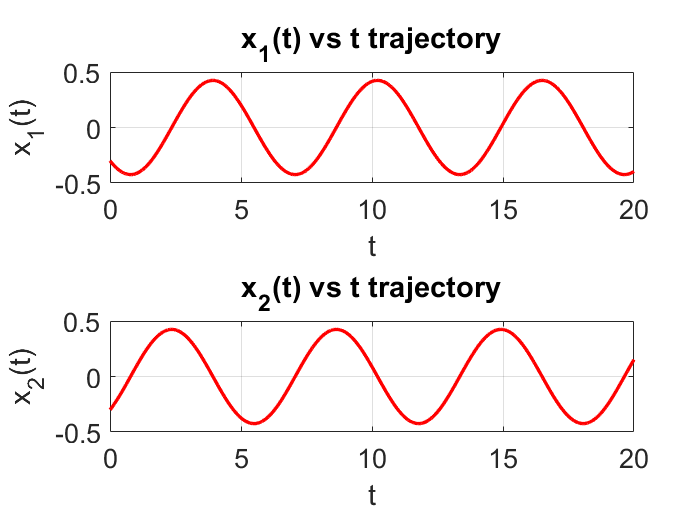

figure
%x1(t) vs t plot
subplot(2,1,1)
plot(t,x(:,1),"LineWidth",2,"Color","r");
grid on
title("x_1(t) vs t trajectory");
ylabel("x_1(t)");
xlabel("t");
set(gca,'Fontsize',16);
%x2(t) vs t plot
subplot(2,1,2)
plot(t,x(:,2),"LineWidth",2,"Color","r");
grid on
title("x_2(t) vs t trajectory");
ylabel("x_2(t)");
xlabel("t");
set(gca,'Fontsize',16);

**c.1. **Here $A = [1,1;-1,1]$ and $x(0) = [-0.05;0.05]$ and time interval [0,5](trajectory will cross the phase portrait limit used before so phase portrait limit is changed) 

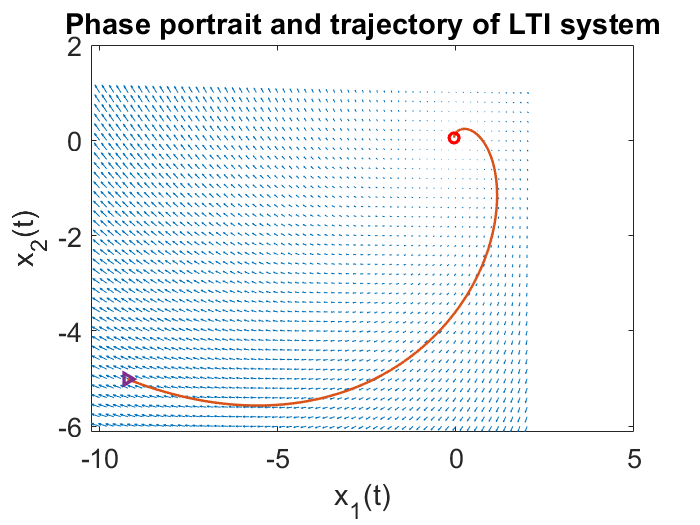

figure
[X3, X4]=meshgrid(-10:0.2:2,-6:0.2:1);
A3=[1 1;-1 1];
vx1 = A3(1,1).*X3 + A3(1,2).*X4;
vx2 = A3(2,1).*X3 + A3(2,2).*X4;
%phase portrait
quiver(X3,X4,vx1,vx2);
[t, x] = ode45(@(t,x)A3*x,0:0.01:5,[-0.05;0.05]);
hold on
%trajectory
plot(x(:,1),x(:,2),'LineWidth',1.5);
title("Phase portrait and trajectory of LTI system");
xlabel("x_1(t)");
ylabel("x_2(t)");
set(gca,'Fontsize',16);
%start_point
plot(x(1,1),x(1,2),"LineWidth",2,"Marker","o","Color","r");
%end_point
plot(x(501,1),x(501,2),"LineWidth",2,"Marker",">");
hold off

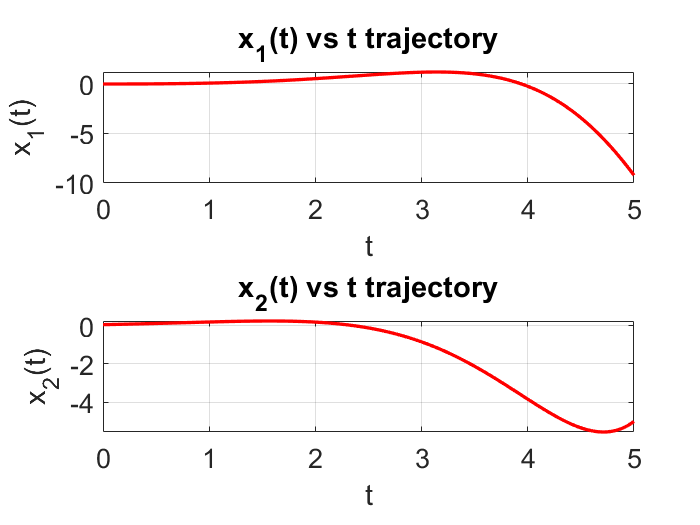

figure
%x1(t) vs t plot
subplot(2,1,1)
plot(t,x(:,1),"LineWidth",2,"Color","r");
grid on
title("x_1(t) vs t trajectory");
ylabel("x_1(t)");
xlabel("t");
set(gca,'Fontsize',16);
%x2(t) vs t plot
subplot(2,1,2)
plot(t,x(:,2),"LineWidth",2,"Color","r");
grid on
title("x_2(t) vs t trajectory");
ylabel("x_2(t)");
xlabel("t");
set(gca,'Fontsize',16);

**c.2. **Now for interval[0,10] (trajectory will cross the phase portrait limit used before so phase portrait limit is changed)

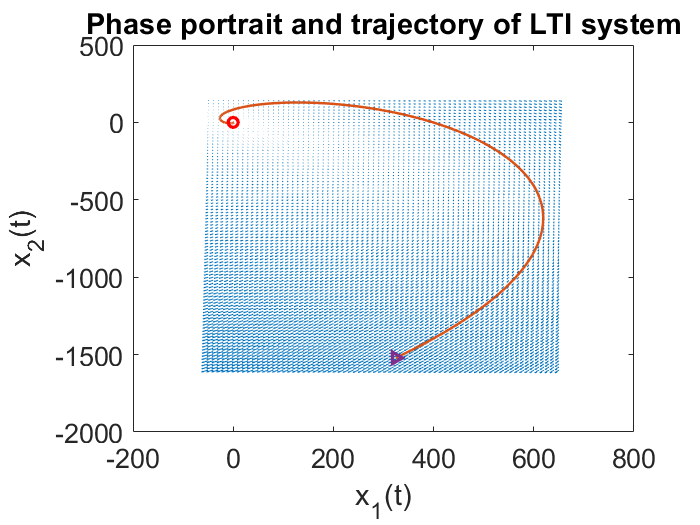

figure
[X5,X6]=meshgrid(-50:10:650,-1600:20:150);
vx1 = A3(1,1).*X5 + A3(1,2).*X6;
vx2 = A3(2,1).*X5 + A3(2,2).*X6;
%phase portrait
quiver(X5,X6,vx1,vx2);
[t, x] = ode45(@(t,x)A3*x,0:0.01:10,[-0.05;0.05]);
hold on
%trajectory
plot(x(:,1),x(:,2),'LineWidth',1.5);
title("Phase portrait and trajectory of LTI system");
xlabel("x_1(t)");
ylabel("x_2(t)");
set(gca,'Fontsize',16);
%start_point
plot(x(1,1),x(1,2),"LineWidth",2,"Marker","o","Color","r");
%end_point
plot(x(1001,1),x(1001,2),"LineWidth",2,"Marker",">");
hold off

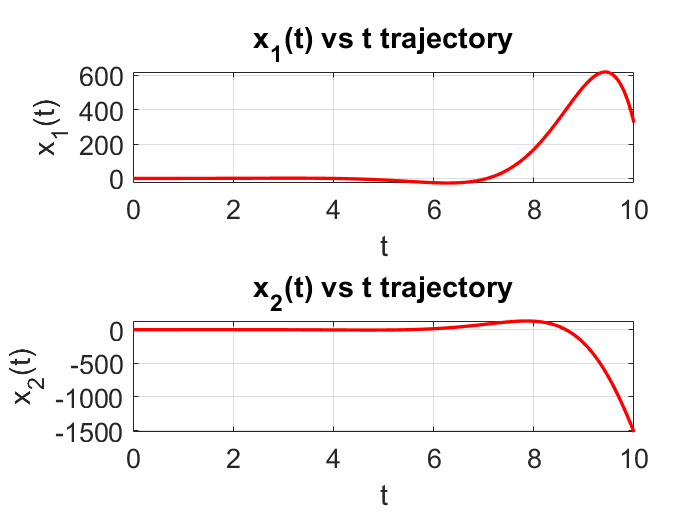

figure
%x1(t) vs t plot
subplot(2,1,1)
plot(t,x(:,1),"LineWidth",2,"Color","r");
grid on
title("x_1(t) vs t trajectory");
ylabel("x_1(t)");
xlabel("t");
set(gca,'Fontsize',16);
%x2(t) vs t plot
subplot(2,1,2)
plot(t,x(:,2),"LineWidth",2,"Color","r");
grid on
title("x_2(t) vs t trajectory");
ylabel("x_2(t)");
xlabel("t");
set(gca,'Fontsize',16);

**d.1. **Here $A = [1,3;1,-1]$ and $x(0) = [0.1;-0.1]$ and time interval [0,10]

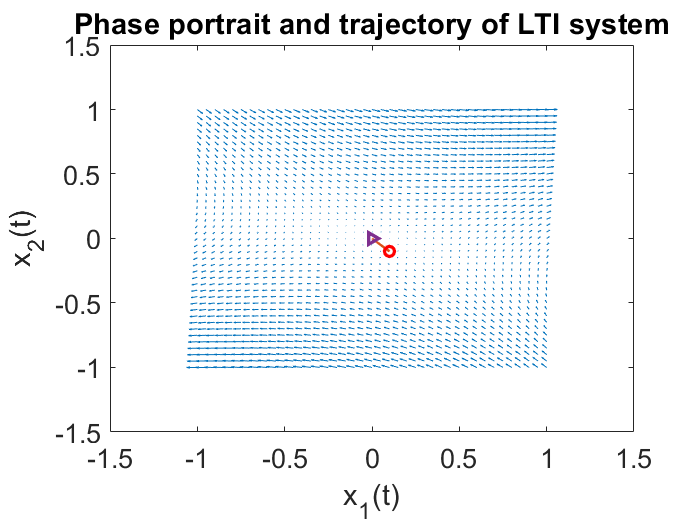

figure
A4=[1 3;1 -1];
vx1 = A4(1,1).*X1 + A4(1,2).*X2;
vx2 = A4(2,1).*X1 + A4(2,2).*X2;
%phase portrait
quiver(X1,X2,vx1,vx2);
[t, x] = ode45(@(t,x)A4*x,0:0.01:10,[0.1;-0.1]);
hold on
%trajectory
plot(x(:,1),x(:,2),'LineWidth',1.5);
title("Phase portrait and trajectory of LTI system");
xlabel("x_1(t)");
ylabel("x_2(t)");
set(gca,'Fontsize',16);
%start_point
plot(x(1,1),x(1,2),"LineWidth",2,"Marker","o","Color","r");
%end_point
plot(x(1001,1),x(1001,2),"LineWidth",2,"Marker",">");
hold off

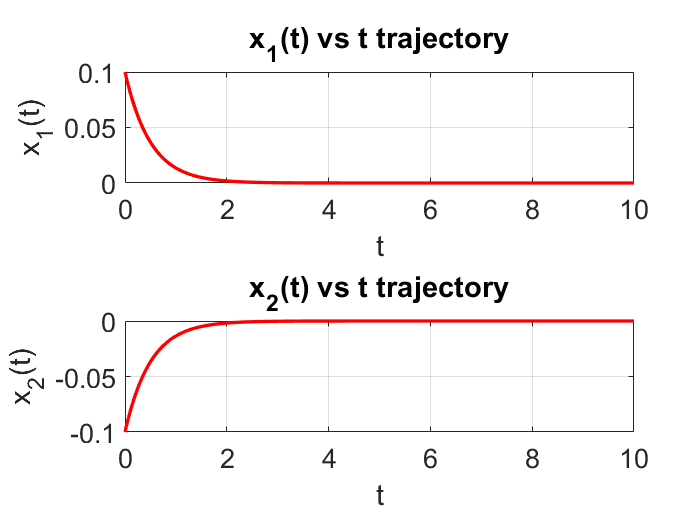

figure
%x1(t) vs t plot
subplot(2,1,1)
plot(t,x(:,1),"LineWidth",2,"Color","r");
grid on
title("x_1(t) vs t trajectory");
ylabel("x_1(t)");
xlabel("t");
set(gca,'Fontsize',16);
%x2(t) vs t plot
subplot(2,1,2)
plot(t,x(:,2),"LineWidth",2,"Color","r");
grid on
title("x_2(t) vs t trajectory");
ylabel("x_2(t)");
xlabel("t");
set(gca,'Fontsize',16);

**d.2. **Now $x(0)=[0.11;-0.1]$ and time interval [0,4]

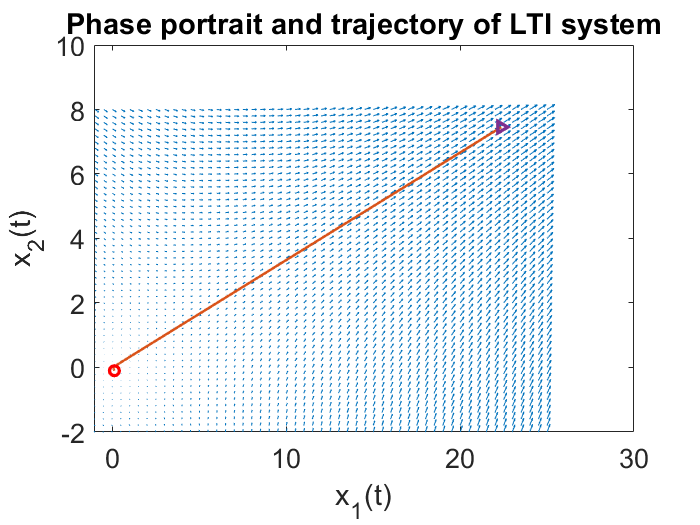

figure
[X7,X8]=meshgrid(-1:0.5:25,-2:0.2:8);
vx1 = A4(1,1).*X7 + A4(1,2).*X8;
vx2 = A4(2,1).*X7 + A4(2,2).*X8;
%phase portrait
quiver(X7,X8,vx1,vx2);
[t, x] = ode45(@(t,x)A4*x,0:0.01:4,[0.11;-0.1]);
hold on
%trajectory
plot(x(:,1),x(:,2),'LineWidth',1.5);
title("Phase portrait and trajectory of LTI system");
xlabel("x_1(t)");
ylabel("x_2(t)");
set(gca,'Fontsize',16);
%start_point
plot(x(1,1),x(1,2),"LineWidth",2,"Marker","o","Color","r");
%end_point
plot(x(401,1),x(401,2),"LineWidth",2,"Marker",">");
hold off

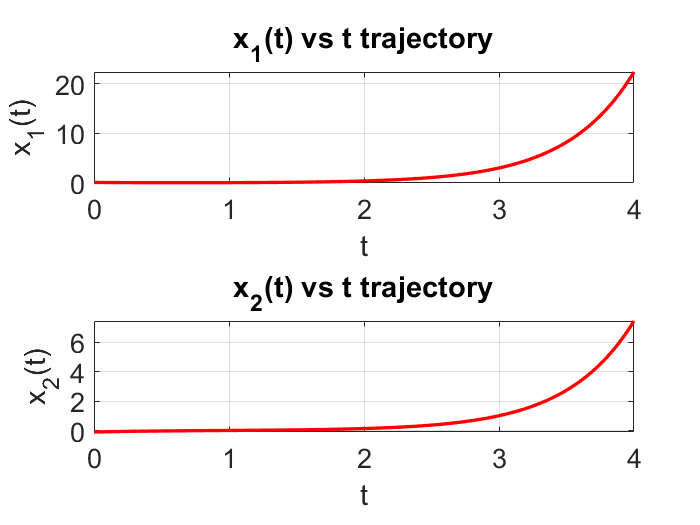

figure
%x1(t) vs t plot
subplot(2,1,1)
plot(t,x(:,1),"LineWidth",2,"Color","r");
grid on
title("x_1(t) vs t trajectory");
ylabel("x_1(t)");
xlabel("t");
set(gca,'Fontsize',16);
%x2(t) vs t plot
subplot(2,1,2)
plot(t,x(:,2),"LineWidth",2,"Color","r");
grid on
title("x_2(t) vs t trajectory");
ylabel("x_2(t)");
xlabel("t");
set(gca,'Fontsize',16);

**d.3. **For $x(0)=[0.1,-0.11]$ over interval [0,4]

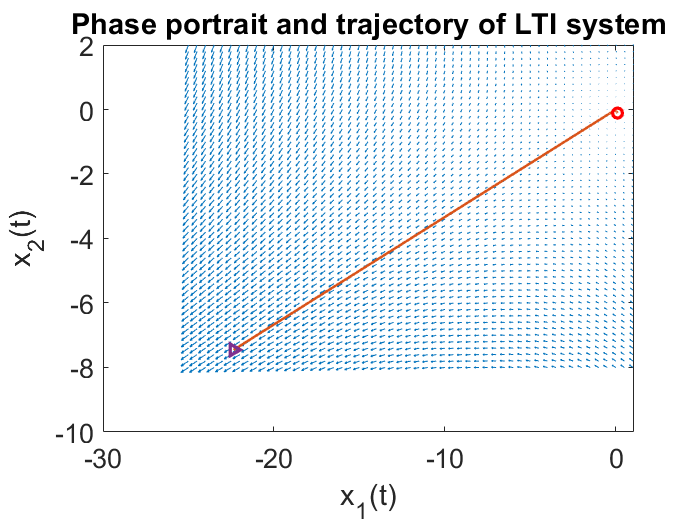

figure
[X9,X10]=meshgrid(-25:0.5:1,-8:0.2:2);
vx1 = A4(1,1).*X9 + A4(1,2).*X10;
vx2 = A4(2,1).*X9 + A4(2,2).*X10;
%phase portrait
quiver(X9,X10,vx1,vx2);
[t, x] = ode45(@(t,x)A4*x,0:0.01:4,[0.1;-0.11]);
hold on
%trajectory
plot(x(:,1),x(:,2),'LineWidth',1.5);
title("Phase portrait and trajectory of LTI system");
xlabel("x_1(t)");
ylabel("x_2(t)");
set(gca,'Fontsize',16);
%start_point
plot(x(1,1),x(1,2),"LineWidth",2,"Marker","o","Color","r");
%end_point
plot(x(401,1),x(401,2),"LineWidth",2,"Marker",">");
hold off

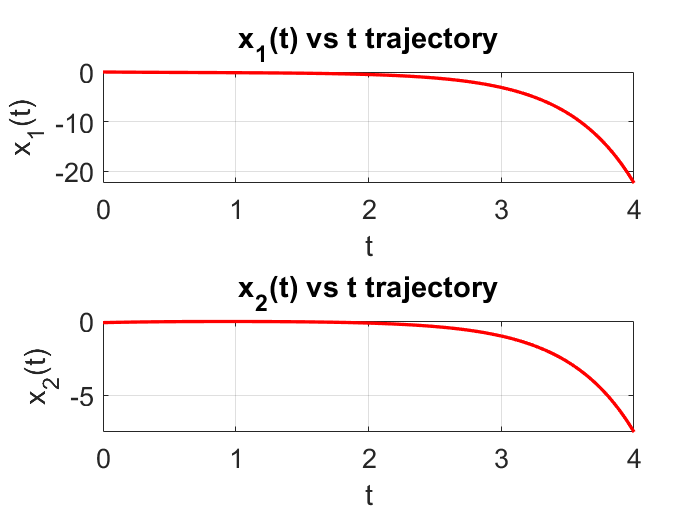

figure
%x1(t) vs t plot
subplot(2,1,1)
plot(t,x(:,1),"LineWidth",2,"Color","r");
grid on
title("x_1(t) vs t trajectory");
ylabel("x_1(t)");
xlabel("t");
set(gca,'Fontsize',16);
%x2(t) vs t plot
subplot(2,1,2)
plot(t,x(:,2),"LineWidth",2,"Color","r");
grid on
title("x_2(t) vs t trajectory");
ylabel("x_2(t)");
xlabel("t");
set(gca,'Fontsize',16);

Now we need to find the eigenvalues of the A matrix given in the plot.

e1=eig(A1)

e1 =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


e2=eig(A2)

e2 =    0.0000 + 1.0000i
   0.0000 - 1.0000i


e3=eig(A3)

e3 =    1.0000 + 1.0000i
   1.0000 - 1.0000i


e4=eig(A4)

e4 =      2
    -2


**Real eigenvalues provide direction in space**, while **complex eigenvalues generate a spiraling or circular motion**(because there is no specific direction as eigenvalues are not real).

In first equation A1 has **complex eigenvalues with negative real part**. So, it generates a **damping spiral trajectory** where distance of trajectory from origin decreases over time.

In second equation, A2 has **complex eigenvalues with 0 real part**. So there is no damping or amplifying effect over time and the trajectory moves in **periodic motion**.

In third equation, A3 has **complex eigenvalues with positive real part**. As explained before, similarly it generates a **gradually amplifying spiral trajectory** where distance of trajectory from origin increases over time.

In fourth equation, A4 has 2 real eigenvalues. So the bigger eigenvalue(here 2) determines the direction of motion of the space. Given **vector [0.1,-0.1] is in the direction of eigenvector with lower eigenvalue** so the propagation of trajectory is **along the eigenvector**. Also due to **negative eigenvalue(-2)** the trajectory **moves toward the origin**, so **along this vector only** the motion of **trajectory is bounded**.

**Even slight deviation from the eigenvector direction** for vectors [0.11,-0.1] or [0.1,-0.11] **forces the trajectory to move towards the eigenvector with higher eigenvalue** (here 2). So according to the vectors' position w.r.t. eigenvector of $\lambda =2$ it follows the vector [3,1] strongly in positive or negative direction after a change in direction from the initial vector. Due to positive eigenvalue the trajectory moves away from origin.